# New features of FSDA 2025B

For a detailed list of what's new in FSDA 2025b please see [http://rosa.unipr.it/FSDA/release_notes.html](http://rosa.unipr.it/FSDA/release_notes.html) 

## Brushing extended to shape files in pcaFS and new option smartEVchart

The first PC already explains more than 0.95^v variability
In what follows we still extract the first 2 PCs
Initial correlation matrix
                 Deposit    Bankrup    UrbanFra    Paym30D    ElecPar    QualLif    Protest    SalaryA    SpendingA    Employm    AddedVa    LowISEE
                 _______    _______    ________    _______    _______    _______    _______    _______    _________    _______    _______    _______

    Deposit        1.00      -0.33      -0.70        0.72       0.58       0.76      -0.14       0.74        0.75        0.79       0.79     

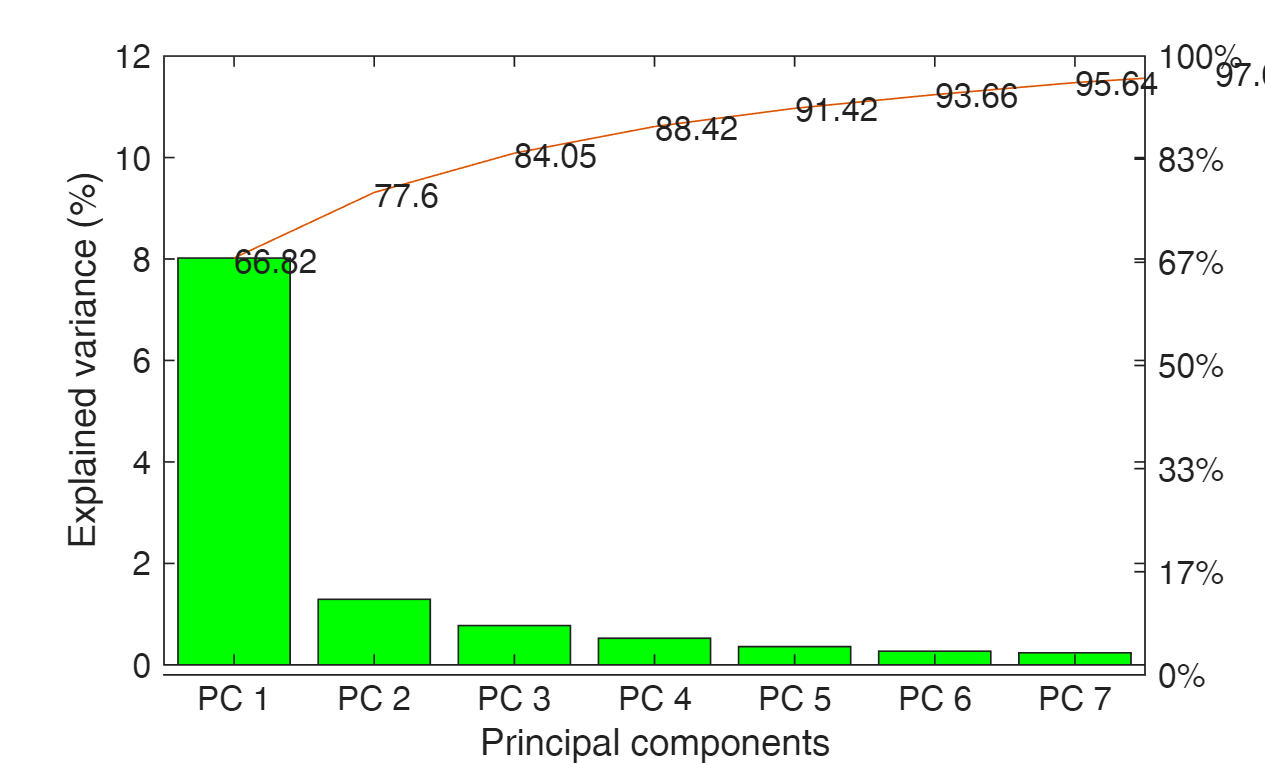

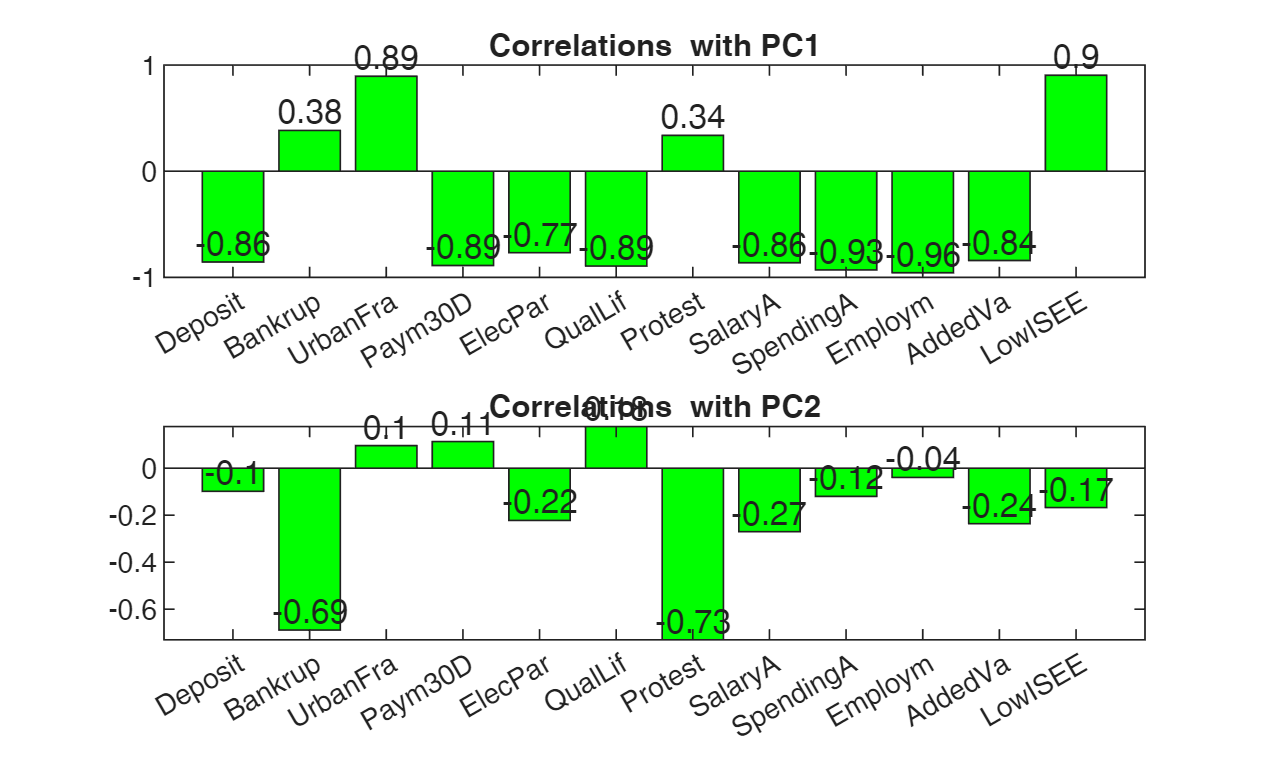

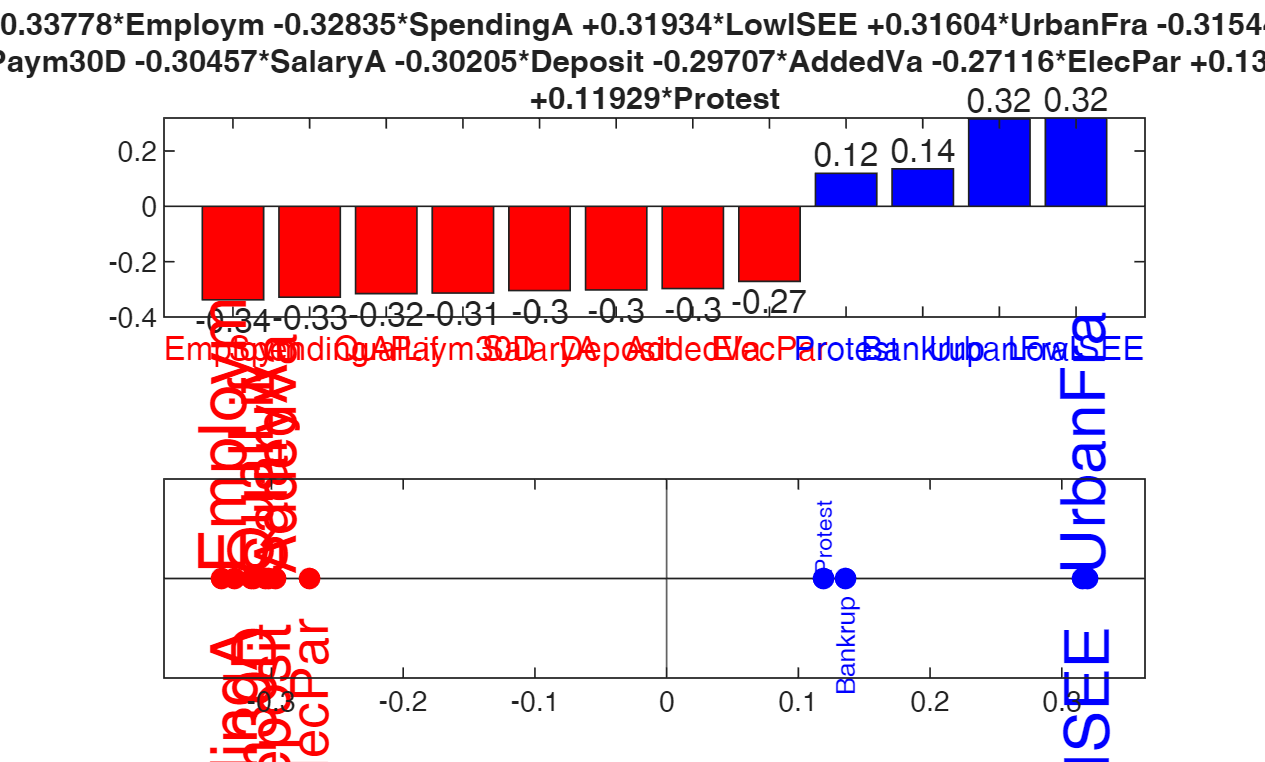

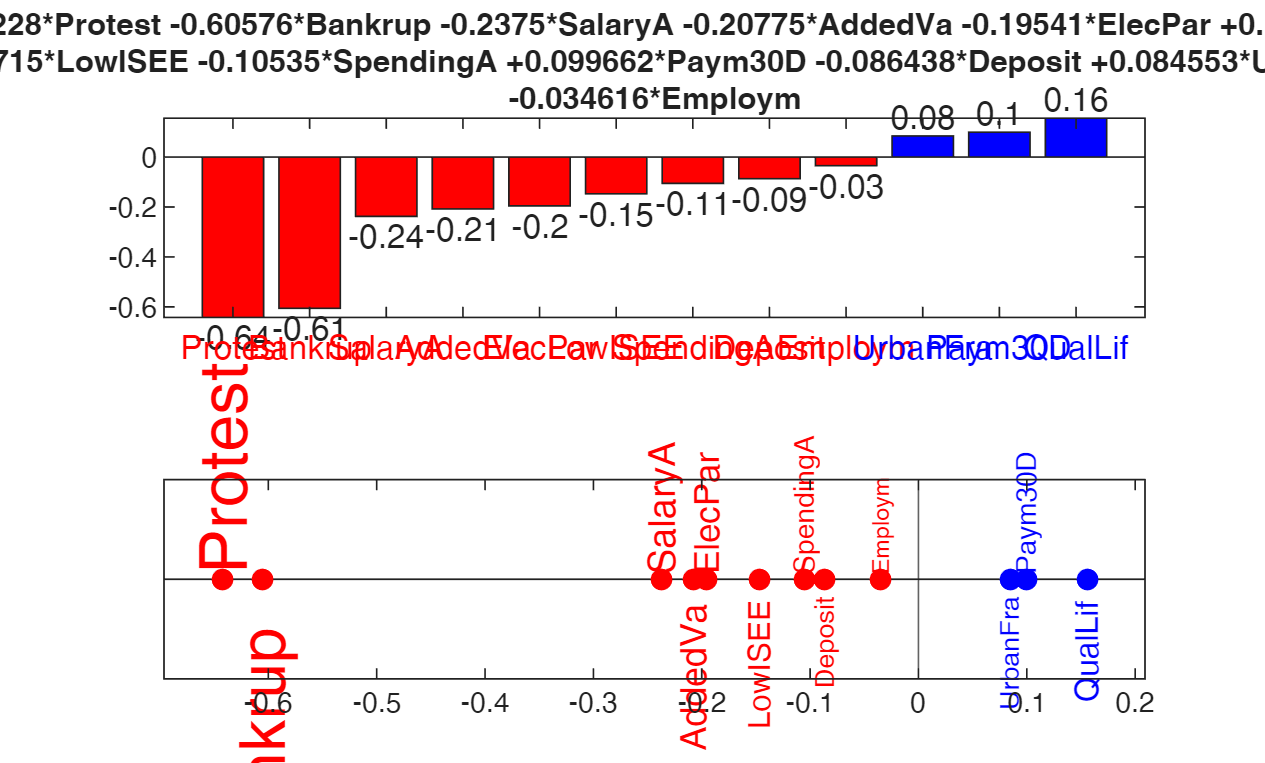

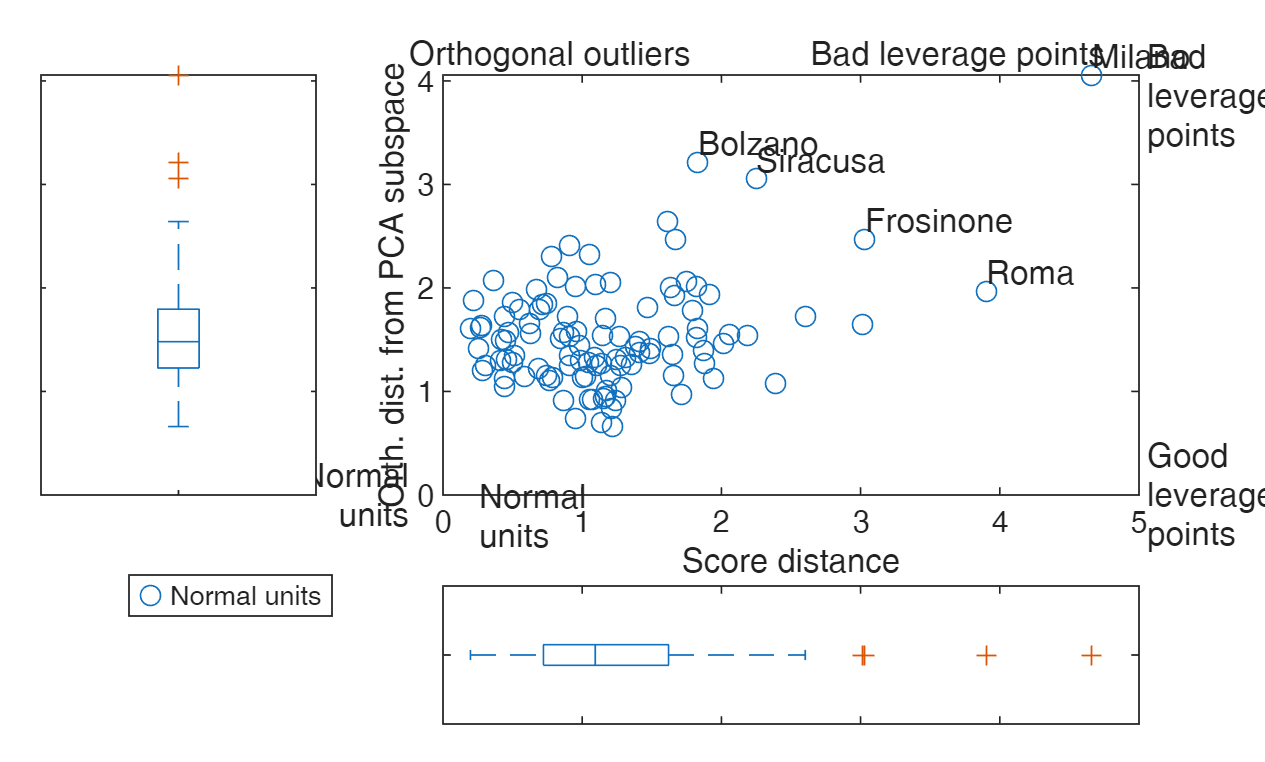

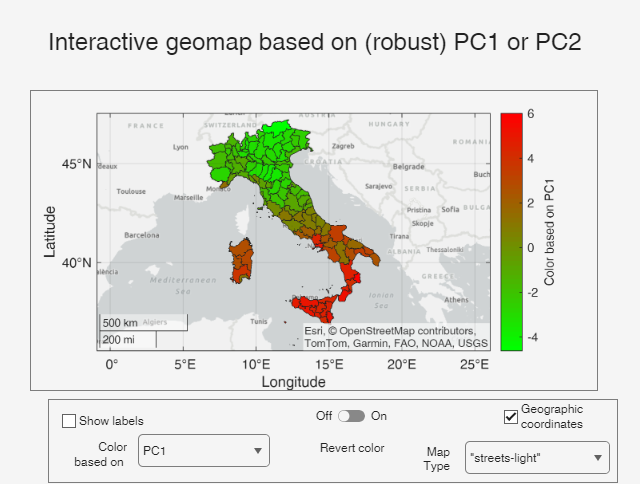

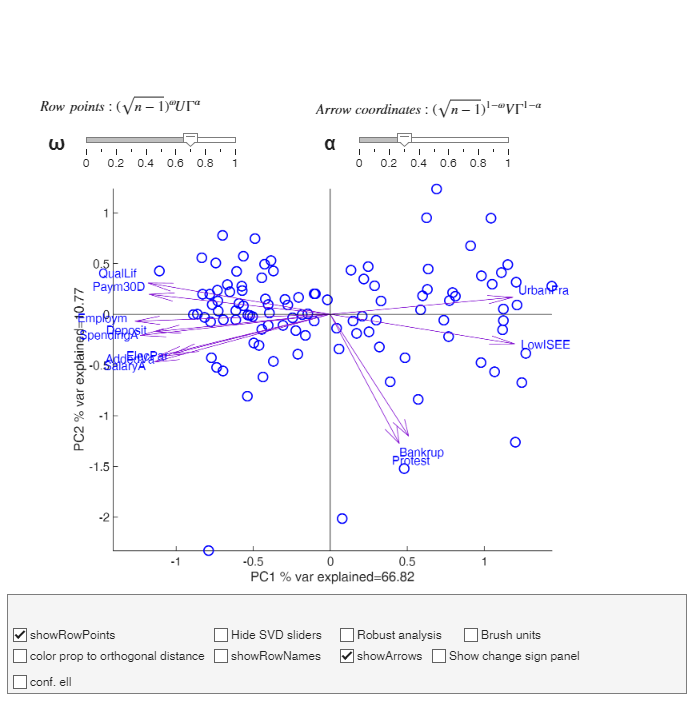

load citiesItaly2024.mat 
ShapeFile=citiesItaly2024.Properties.UserData{1}; 
out=pcaFS(citiesItaly2024,'ShapeFile',ShapeFile,'smartEVchart',true);

In the biplot GUI when conf. ell is selected when showRowNames is active, just the labels of the units which are outside of the confidence ellipse are shown.

## New function `pcaProjection` 

Projection of points into a low dimensional space. 

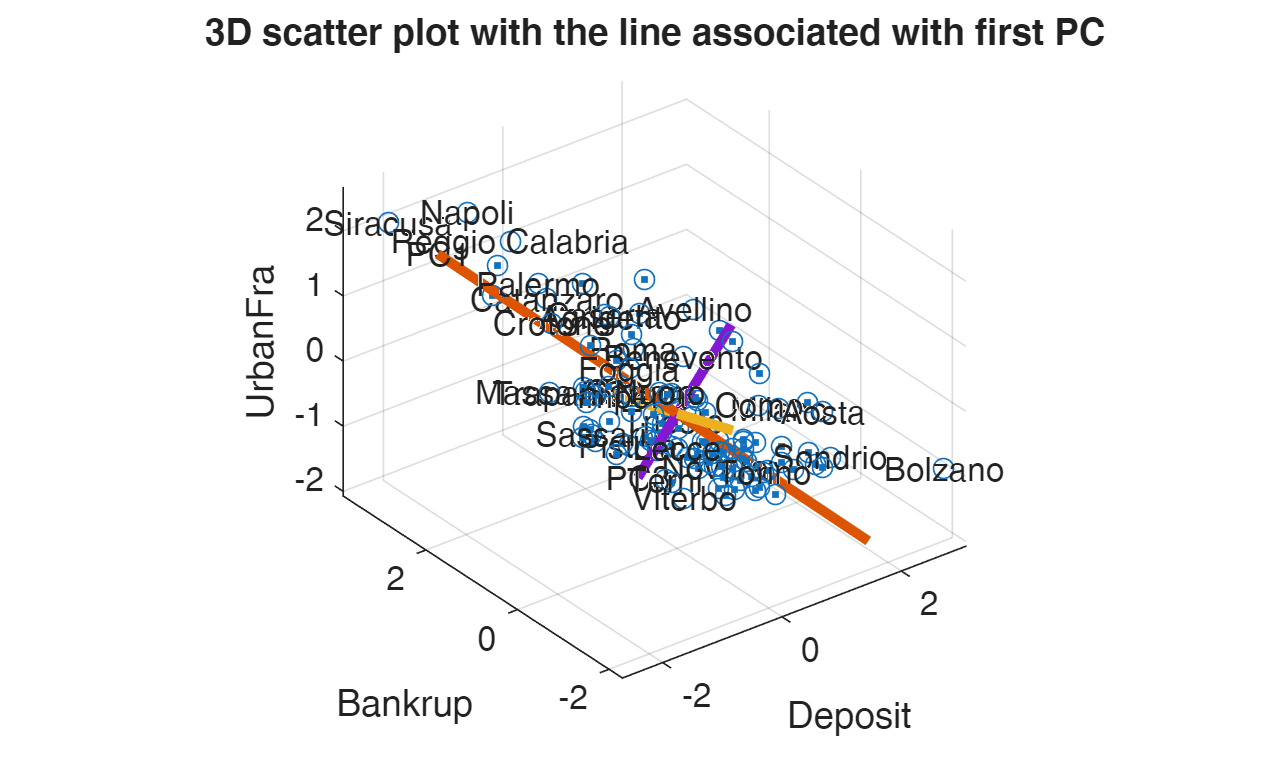

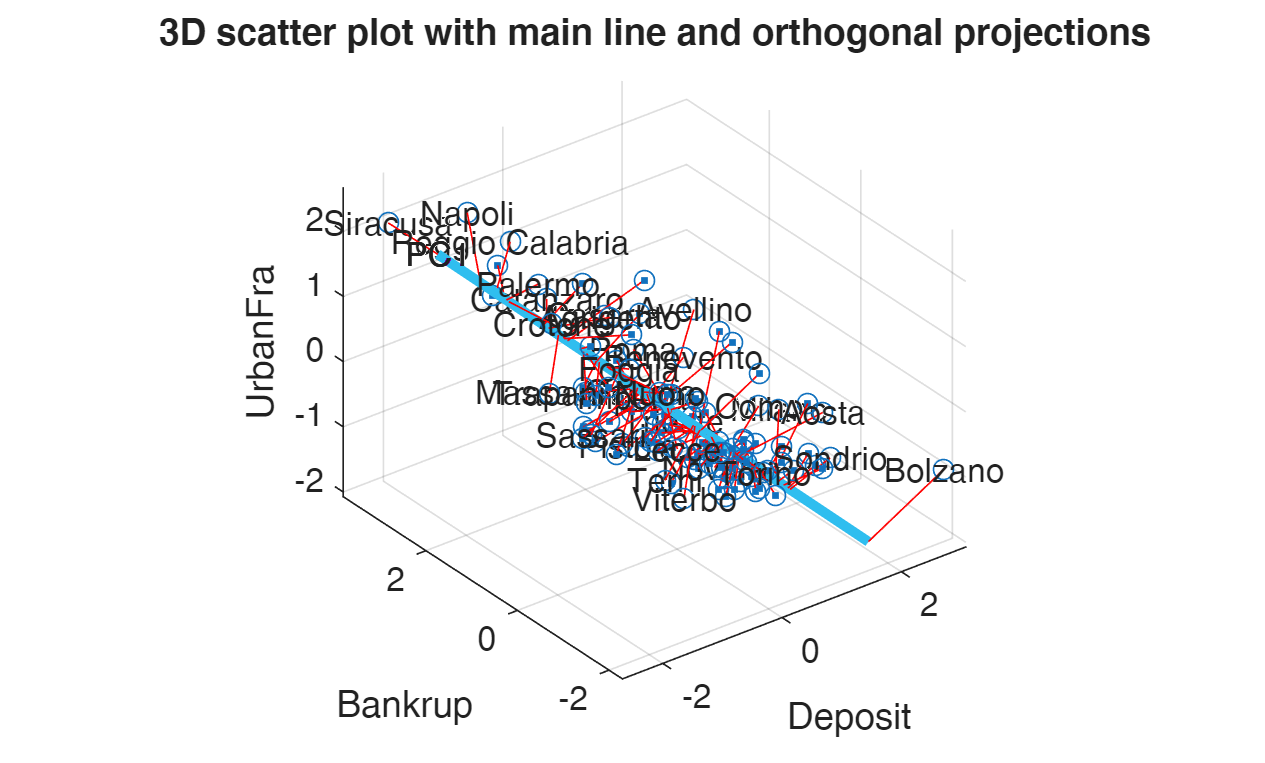

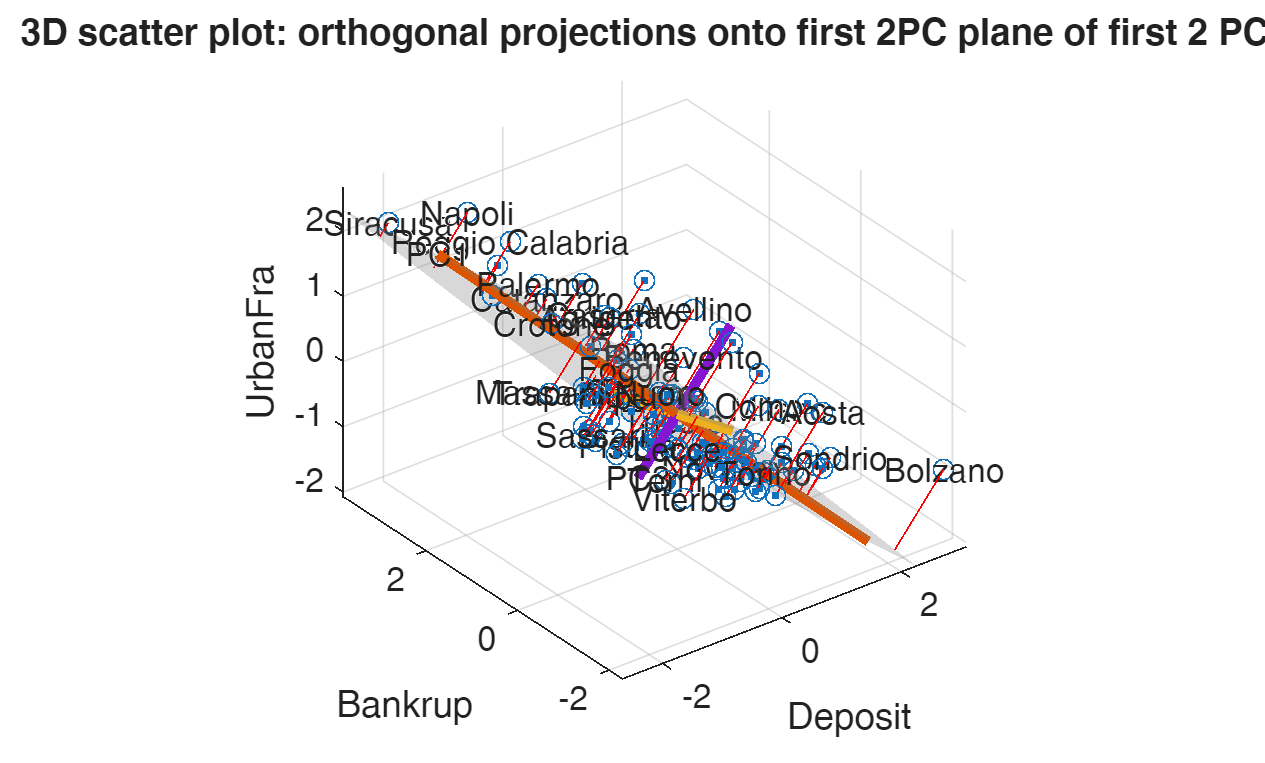

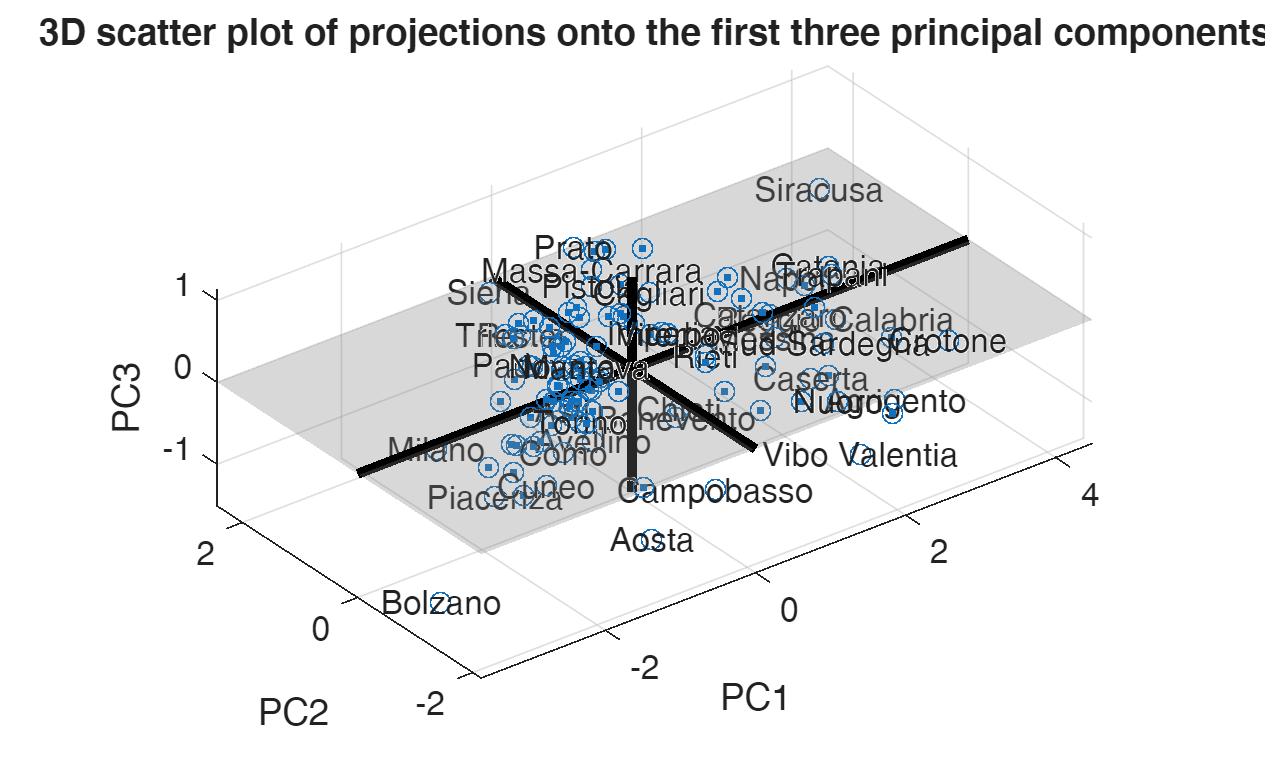

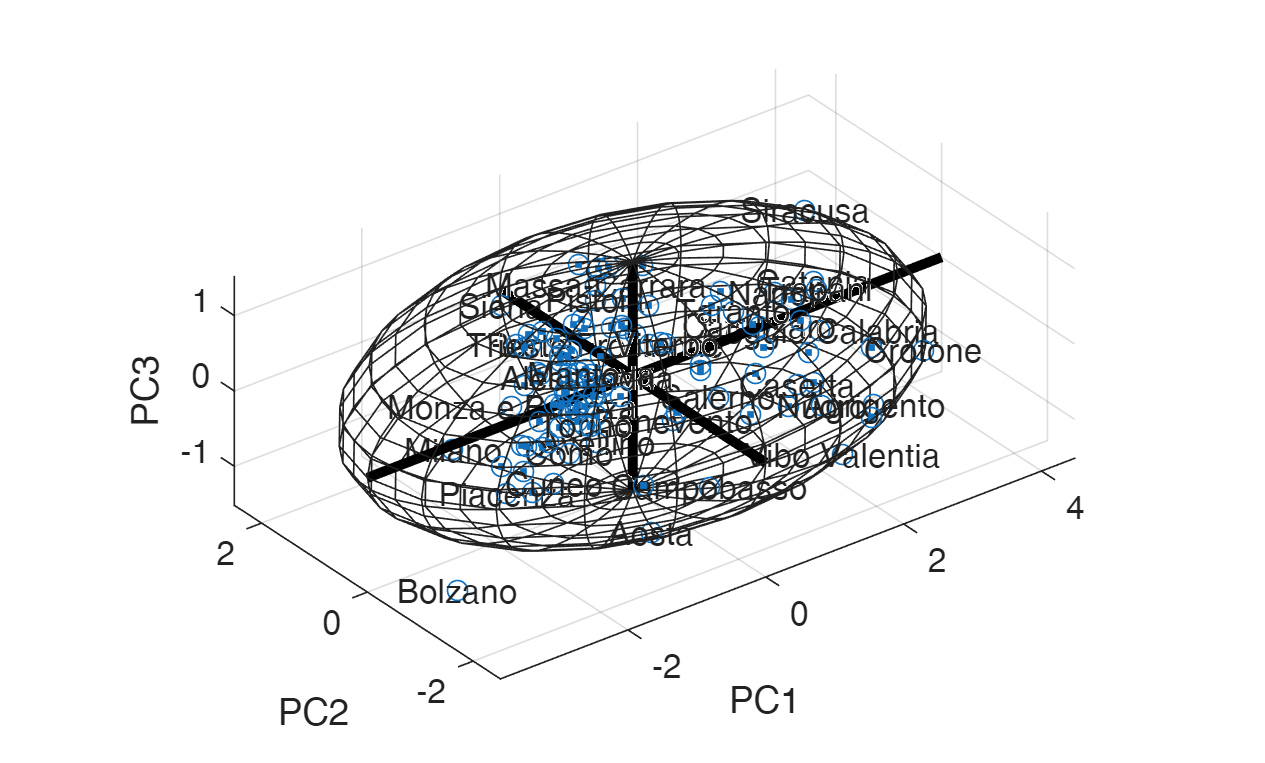

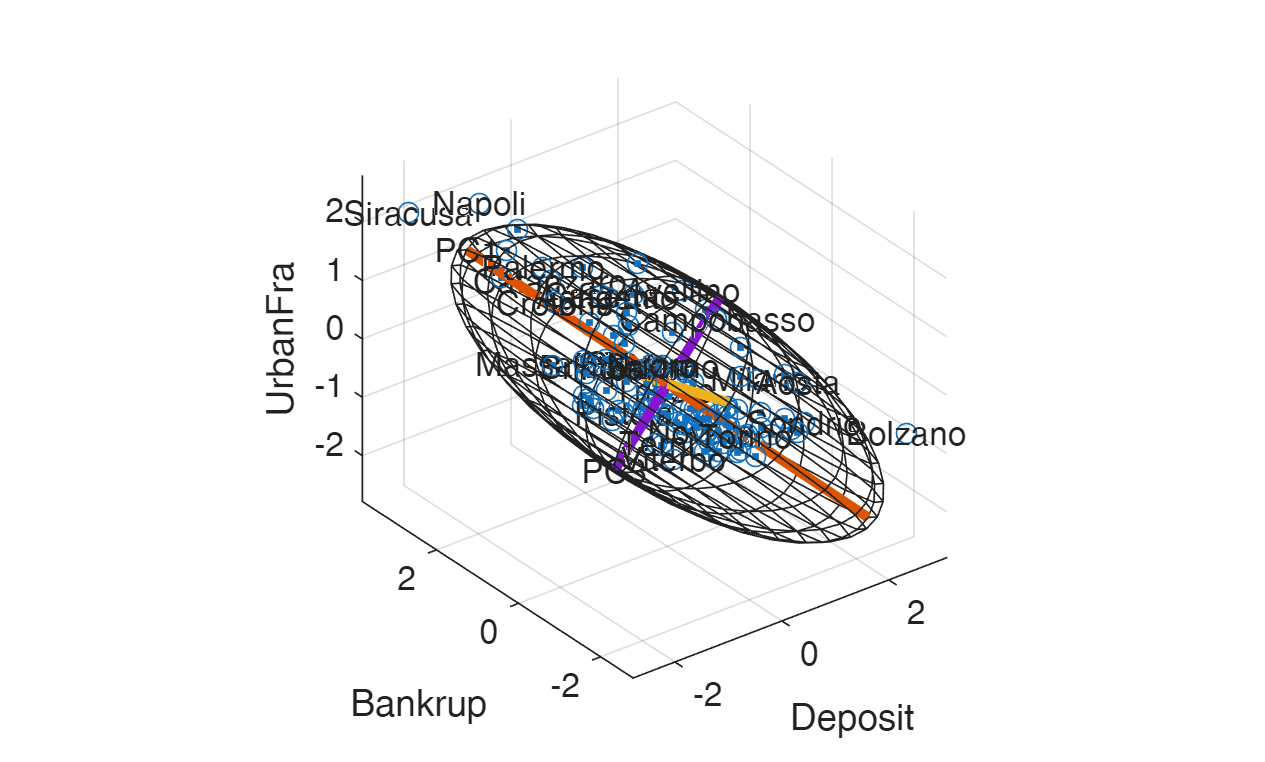

load citiesItaly2024.mat
pcaProjection(citiesItaly2024);

## New option plots in `grpstatsFS`

Confidence intervals shown as errorbar (with grouping variables)

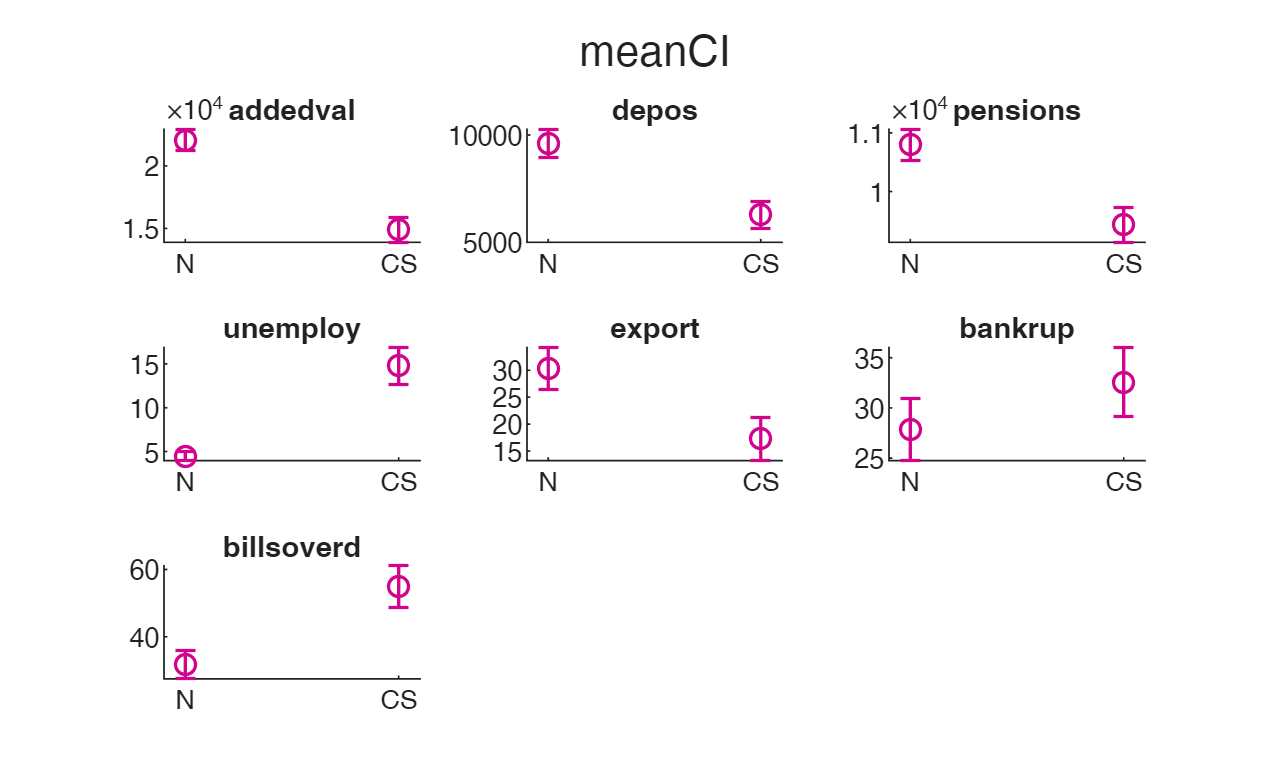

figure
load citiesItaly.mat
zone=[repelem("N",46) repelem("CS",57)]';
citiesItaly.zone=zone;
TBL=grpstatsFS(citiesItaly,'zone',"meanci", 'plots',1);

Note that the only variable for which confidence ellipses overlap is bankrup (that is percentage of bankruptcy declarations on active companies). 

## New function `polarhistogramFS`

Polar histograms (with grouping variables). Legends are clickable

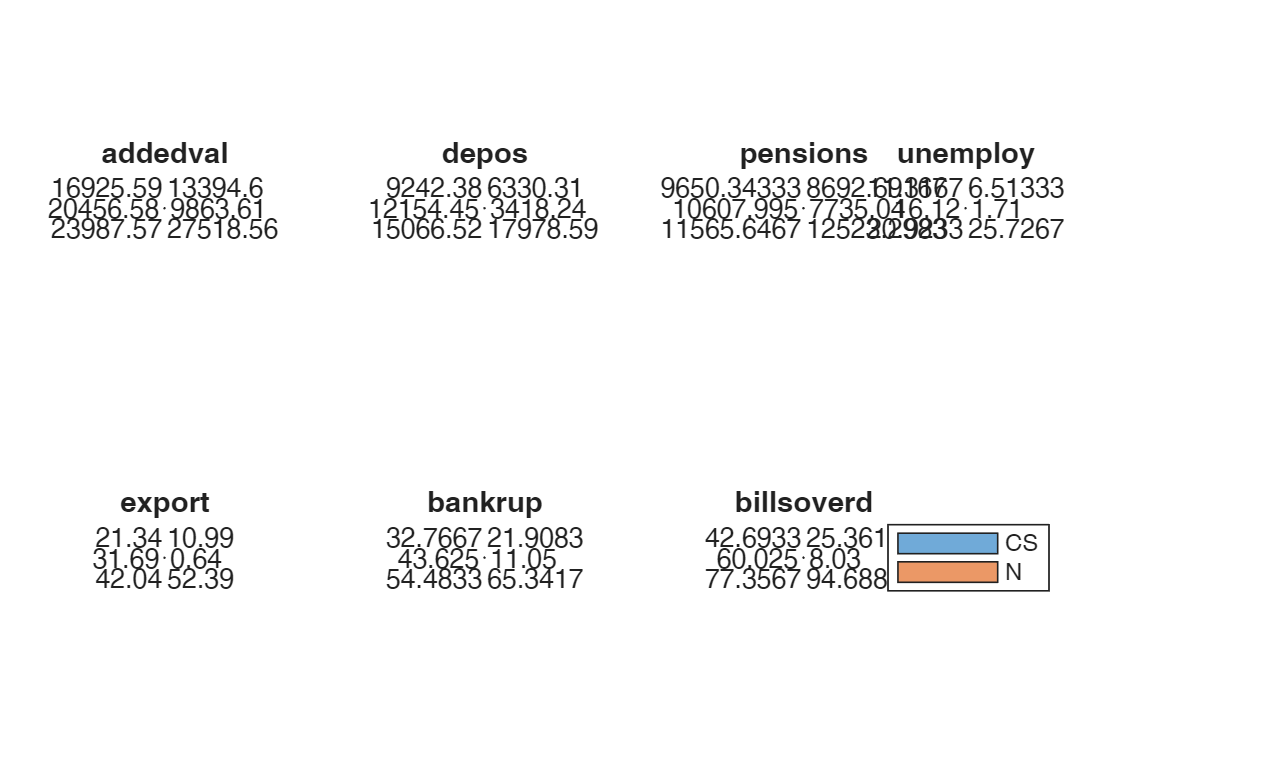

figure
load citiesItaly.mat
zone=[repelem("N",46) repelem("CS",57)]';
TBL=polarhistogramFS(citiesItaly,'groupvars',zone);

## `N`ew function `corrinv`

Quantiles of the sampling distribution of the sample correlation coefficient *r*

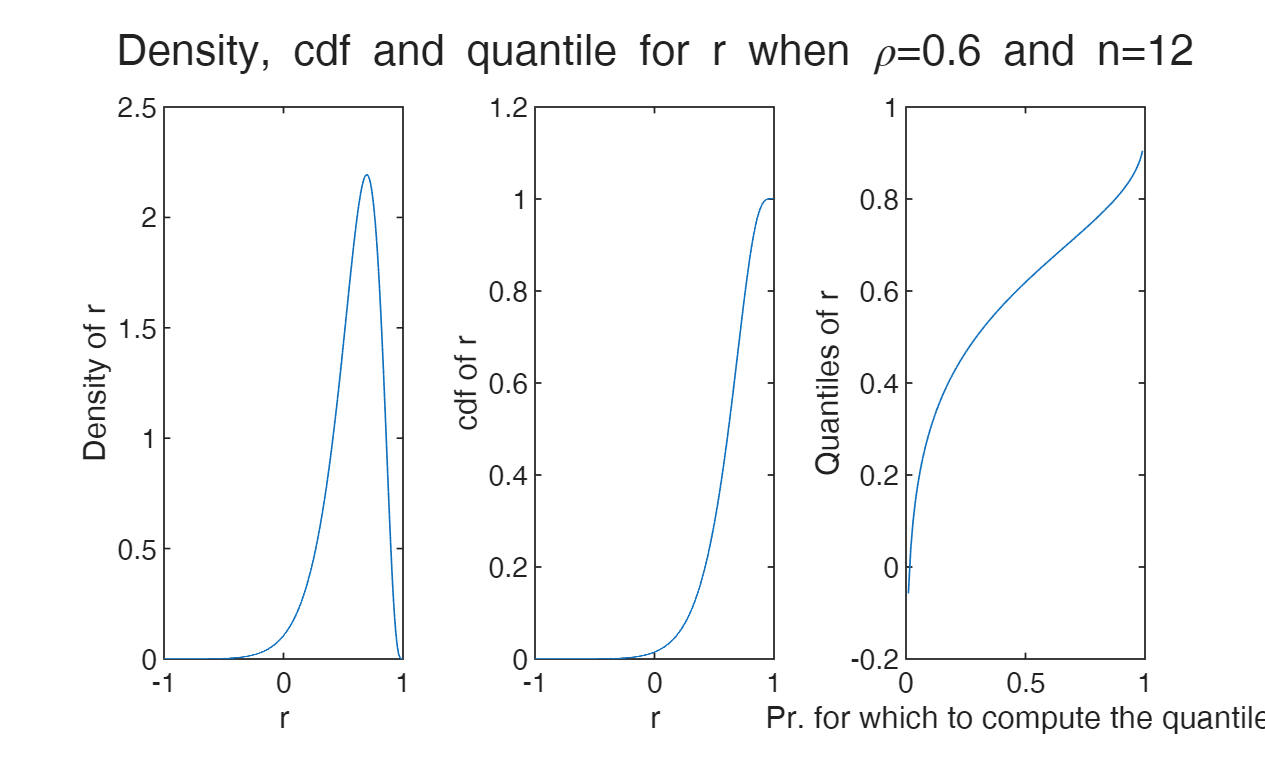

figure
rho=0.6; % Population correlation
n=12;  % Sample size
x = linspace(-1, 1, 1000);

tiledlayout('horizontal')
nexttile
plot(x,corrpdf(x,rho,n))
xlabel('r')

ylabel('Density of r')
nexttile
plot(x,corrcdf(x,rho,n))
xlabel('r')
ylabel('cdf of r')
nexttile
q=0:0.01:0.99;
plot(q,corrinv(q,rho,n))
ylabel('Quantiles of r')
xlabel('Pr. for which to compute the quantiles')

sgtitle(['Density, cdf and quantile for r when \rho=' num2str(rho) ' and n=' num2str(n)])